%% Construcción de detección de bordes Canny

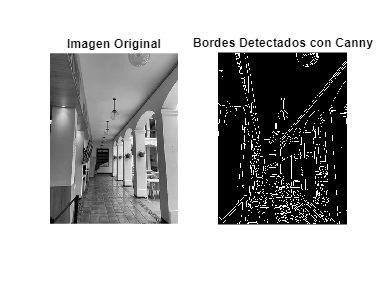

%% USO MEDIANTE CANNY INTEGRADO EN MATLAB

% Leer la imagen
I = imread('img3.jpeg'); % Reemplaza 'nombre_de_la_imagen.jpg' con el nombre de tu imagen

% Convertir a escala de grises si es necesario
if size(I, 3) == 3
    I = rgb2gray(I);
end

% Aplicar el detector de bordes de Canny
edges = edge(I, 'Canny');

% Mostrar la imagen original y la imagen con bordes detectados
figure;
subplot(1, 2, 1);
imshow(I);
title('Imagen Original');

subplot(1, 2, 2);
imshow(edges);
title('Bordes Detectados con Canny');

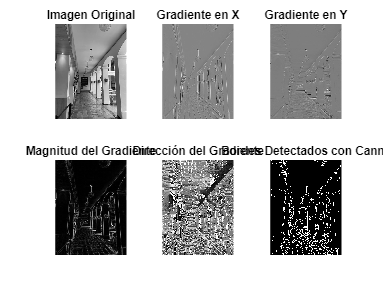

%% CREACIÓN DEL CANNY SIN SUAVIZADO


% Leer la imagen
I = imread('img3.jpeg'); % Reemplaza 'nombre_de_la_imagen.jpg' con el nombre de tu imagen

% Convertir a escala de grises si es necesario
if size(I, 3) == 3
    I = rgb2gray(I);
end

% Paso 1: Suavizar la imagen con un filtro gaussiano
sigma = 1.4;
gaussianFilter = fspecial('gaussian', [5 5], sigma);
I_smooth = imfilter(I, gaussianFilter, 'replicate');

% Paso 2: Calcular el gradiente de la imagen
[Gx, Gy] = gradient(double(I));
magnitude = sqrt(Gx.^2 + Gy.^2);
direction = atan2(Gy, Gx);

% Paso 3: Supresión de no-máximos
[m, n] = size(I);
Z = zeros(m, n);

angle = direction * (180 / pi);
angle(angle < 0) = angle(angle < 0) + 180;

for i = 2:m-1
    for j = 2:n-1
        try
            q = 255;
            r = 255;
            
            % Angle 0
            if ((0 <= angle(i,j) < 22.5) || (157.5 <= angle(i,j) <= 180))
                q = magnitude(i, j+1);
                r = magnitude(i, j-1);
            % Angle 45
            elseif (22.5 <= angle(i,j) < 67.5)
                q = magnitude(i+1, j-1);
                r = magnitude(i-1, j+1);
            % Angle 90
            elseif (67.5 <= angle(i,j) < 112.5)
                q = magnitude(i+1, j);
                r = magnitude(i-1, j);
            % Angle 135
            elseif (112.5 <= angle(i,j) < 157.5)
                q = magnitude(i-1, j-1);
                r = magnitude(i+1, j+1);
            end
            
            if (magnitude(i,j) >= q) && (magnitude(i,j) >= r)
                Z(i,j) = magnitude(i,j);
            else
                Z(i,j) = 0;
            end
            
        catch
        end
    end
end

% Paso 4: Aplicar umbrales con histéresis
lowThreshold = 0.05 * max(max(Z));
highThreshold = 0.15 * max(max(Z));

edgeImage = zeros(m, n);

strong = 255;
weak = 75;

strong_i = [];
strong_j = [];
weak_i = [];
weak_j = [];

for i = 1:m
    for j = 1:n
        if Z(i, j) >= highThreshold
            edgeImage(i, j) = strong;
            strong_i = [strong_i i];
            strong_j = [strong_j j];
        elseif Z(i, j) >= lowThreshold
            edgeImage(i, j) = weak;
            weak_i = [weak_i i];
            weak_j = [weak_j j];
        end
    end
end

for k = 1:length(strong_i)
    i = strong_i(k);
    j = strong_j(k);
    for x = -1:1
        for y = -1:1
            if (i+x > 0 && i+x <= m && j+y > 0 && j+y <= n)
                if (edgeImage(i+x, j+y) == weak)
                    edgeImage(i+x, j+y) = strong;
                end
            end
        end
    end
end

% Mostrar la imagen original, los gradientes y el campo vectorial
figure;
subplot(2, 3, 1);
imshow(I);
title('Imagen Original');

subplot(2, 3, 2);
imshow(mat2gray(Gx));
title('Gradiente en X');

subplot(2, 3, 3);
imshow(mat2gray(Gy));
title('Gradiente en Y');

subplot(2, 3, 4);
imshow(mat2gray(magnitude));
title('Magnitud del Gradiente');

subplot(2, 3, 5);
imshow(mat2gray(direction));
title('Dirección del Gradiente');

subplot(2, 3, 6);
imshow(edgeImage);
title('Bordes Detectados con Canny');

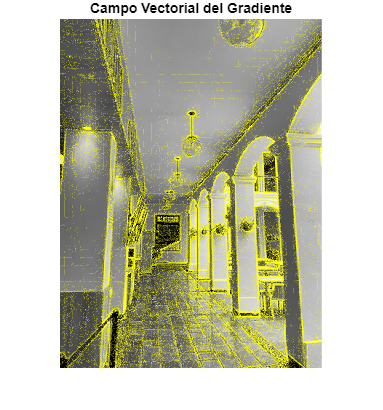


% Añadir el campo vectorial del gradiente
figure;
imshow(I);
title('Campo Vectorial del Gradiente');
hold on;
quiver(Gx, Gy, 'y');
hold off;

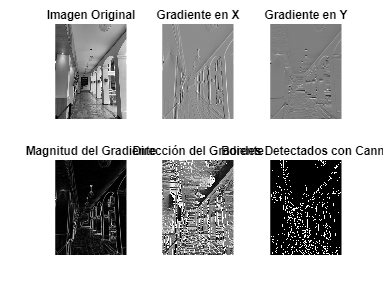

%% CREACIÓN DEL CANNY CON SUAVIZADO


% Leer la imagen
I = imread('img3.jpeg'); % Reemplaza 'nombre_de_la_imagen.jpg' con el nombre de tu imagen

% Convertir a escala de grises si es necesario
if size(I, 3) == 3
    I = rgb2gray(I);
end

% Paso 1: Suavizar la imagen con un filtro gaussiano
sigma = 1.4;
gaussianFilter = fspecial('gaussian', [5 5], sigma);
I_smooth = imfilter(I, gaussianFilter, 'replicate');

% Paso 2: Calcular el gradiente de la imagen
[Gx, Gy] = gradient(double(I_smooth));
magnitude = sqrt(Gx.^2 + Gy.^2);
direction = atan2(Gy, Gx);

% Paso 3: Supresión de no-máximos
[m, n] = size(I);
Z = zeros(m, n);

angle = direction * (180 / pi);
angle(angle < 0) = angle(angle < 0) + 180;

for i = 2:m-1
    for j = 2:n-1
        try
            q = 255;
            r = 255;
            
            % Angle 0
            if ((0 <= angle(i,j) < 22.5) || (157.5 <= angle(i,j) <= 180))
                q = magnitude(i, j+1);
                r = magnitude(i, j-1);
            % Angle 45
            elseif (22.5 <= angle(i,j) < 67.5)
                q = magnitude(i+1, j-1);
                r = magnitude(i-1, j+1);
            % Angle 90
            elseif (67.5 <= angle(i,j) < 112.5)
                q = magnitude(i+1, j);
                r = magnitude(i-1, j);
            % Angle 135
            elseif (112.5 <= angle(i,j) < 157.5)
                q = magnitude(i-1, j-1);
                r = magnitude(i+1, j+1);
            end
            
            if (magnitude(i,j) >= q) && (magnitude(i,j) >= r)
                Z(i,j) = magnitude(i,j);
            else
                Z(i,j) = 0;
            end
            
        catch
        end
    end
end

% Paso 4: Aplicar umbrales con histéresis
lowThreshold = 0.05 * max(max(Z));
highThreshold = 0.15 * max(max(Z));

edgeImage = zeros(m, n);

strong = 255;
weak = 75;

strong_i = [];
strong_j = [];
weak_i = [];
weak_j = [];

for i = 1:m
    for j = 1:n
        if Z(i, j) >= highThreshold
            edgeImage(i, j) = strong;
            strong_i = [strong_i i];
            strong_j = [strong_j j];
        elseif Z(i, j) >= lowThreshold
            edgeImage(i, j) = weak;
            weak_i = [weak_i i];
            weak_j = [weak_j j];
        end
    end
end

for k = 1:length(strong_i)
    i = strong_i(k);
    j = strong_j(k);
    for x = -1:1
        for y = -1:1
            if (i+x > 0 && i+x <= m && j+y > 0 && j+y <= n)
                if (edgeImage(i+x, j+y) == weak)
                    edgeImage(i+x, j+y) = strong;
                end
            end
        end
    end
end

% Mostrar la imagen original, los gradientes y el campo vectorial
figure;
subplot(2, 3, 1);
imshow(I);
title('Imagen Original');

subplot(2, 3, 2);
imshow(mat2gray(Gx));
title('Gradiente en X');

subplot(2, 3, 3);
imshow(mat2gray(Gy));
title('Gradiente en Y');

subplot(2, 3, 4);
imshow(mat2gray(magnitude));
title('Magnitud del Gradiente');

subplot(2, 3, 5);
imshow(mat2gray(direction));
title('Dirección del Gradiente');

subplot(2, 3, 6);
imshow(edgeImage);
title('Bordes Detectados con Canny');

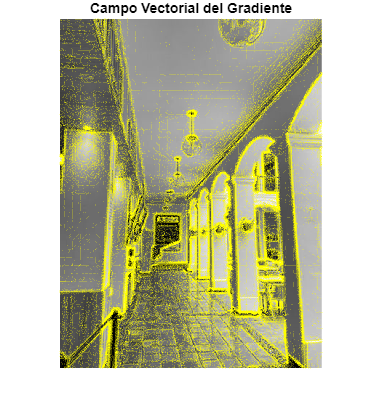


% Añadir el campo vectorial del gradiente
figure;
imshow(I);
title('Campo Vectorial del Gradiente');
hold on;
quiver(Gx, Gy, 'y');
hold off;